### **SW and Methods for Statistical Analysis**

# **Time Series Analysis of Nvidia Stock Prices (2012-2024) - **

# **The Univariate Case**

In this MATLAB Livebook, a comprehensive Univariate Time Series Analysis will be carried out to study the stock prices and returns of the most capitalized (as of June 24th) company of the world, Nvidia Corporation (**NASDAQ: NVDA**).

This livebook, the data and supplemental materials will be available on this [Github Repository](https://github.com/trarez/EsameSoftware).

The livebook will mainly have a mix of programming, statistical and financial notions. Technical and non-intuitive aspects of the scripts will be explained in the cells with "%%".

*Where do I gather information for this project? *Main Resources:

- [Analysis of Financial Time Series](https://www.wiley.com/en-ca/Analysis+of+Financial+Time+Series%2C+3rd+Edition-p-9780470414354) by Ruey S. Tsay;

- [Time Series Analysis with Applications in R](https://link.springer.com/book/10.1007/978-0-387-75959-3) by Jonathan D. Cryer and Kung-Sik Chan;

- [Forecasting: Principles and Practices](https://otexts.com/fpp3/) by Rob J. Hyndman and George Athanasopoulos;

- Professor's slides;

- MATLAB Tutorials;

- Investopedia;

- Youtube Tutorials: [Economic Time Series Modelling in MATLAB](https://www.youtube.com/watch?v=UCChM5Mul_E); [Power Comparison of Normality Tests](https://www.youtube.com/watch?v=ioJD3RTUUXE)

- English Wikipedia (with a grain of salt);

- ... and a bit of Gemini LLM (with two grains of salt!).

## Data Importing and Descriptive Statistics

The data have been downloaded at June 24th on Yahoo! Finance and imported on Github for easier accessibility.

df = readtable("https://raw.githubusercontent.com/trarez/EsameSoftware/main/Nvidia%20Stock%20Prices.csv","VariableNamingRule","preserve")

df = 2915×7 table
       Date        Open       High        Low       Close     Adj Close      Volume  
    __________    _______    _______    _______    _______    _________    __________

    2012-11-20     0.2895    0.29075    0.28425    0.28725     0.26517     3.3698e+08
    2012-11-21    0.28725    0.29625      0.287     0.2955     0.27279     4.2231e+08
    2012-11-23    0.29675      0.301    0.29525     0.2975     0.27464     2.7693e+08
    2012-11-26      0.298     0.3035     0.2975    0.30275     0.27948      3.646e+08
    2012-11-27     0.3015     0.3085      0.299      0.304     0.28064      4.514e+08
    2012-11-28    0.30275      0.308      0.299     0.3065     0.28294     3.9833e+08
    2012-11-29      0.307     0.3085        0.3      0.

rng(0, "twister") % for eventual reproducibility

During a trading day, the stock prices vary. Yahoo! Finance provide basic intra-day distributional values. With these it might be possible to deepen the analysis (for example, by building *candlesticks *on a time series*, *figure below), but for now let's just consider **adjusted close** prices.

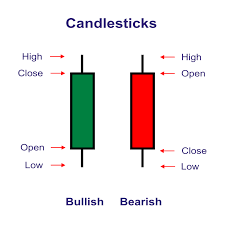

The closing price is the raw price, which is just the cash value of the last transacted price before the market closes. The adjusted closing price factors in anything that might affect the stock price after the market closes, for example dividend payments to shareholders, as shown in the formula below (Source:[ *Investopedia*](https://www.investopedia.com/terms/a/adjusted_closing_price.asp)*). *


$$R_t = \frac{P_t + D_t}{P_{t-1}} - 1$$


df = df(:, {'Date', 'Adj Close'});
dates = df.Date;
prices = df.("Adj Close");

It's important to keep in mind that trading days differ from actual days, because during the weekend and holidays the stock market is closed.

There are some strategies to deal with this:

- Leave the data as they are: technically no information is lost, because no trading occurs

- Missing Data Imputation

- ...

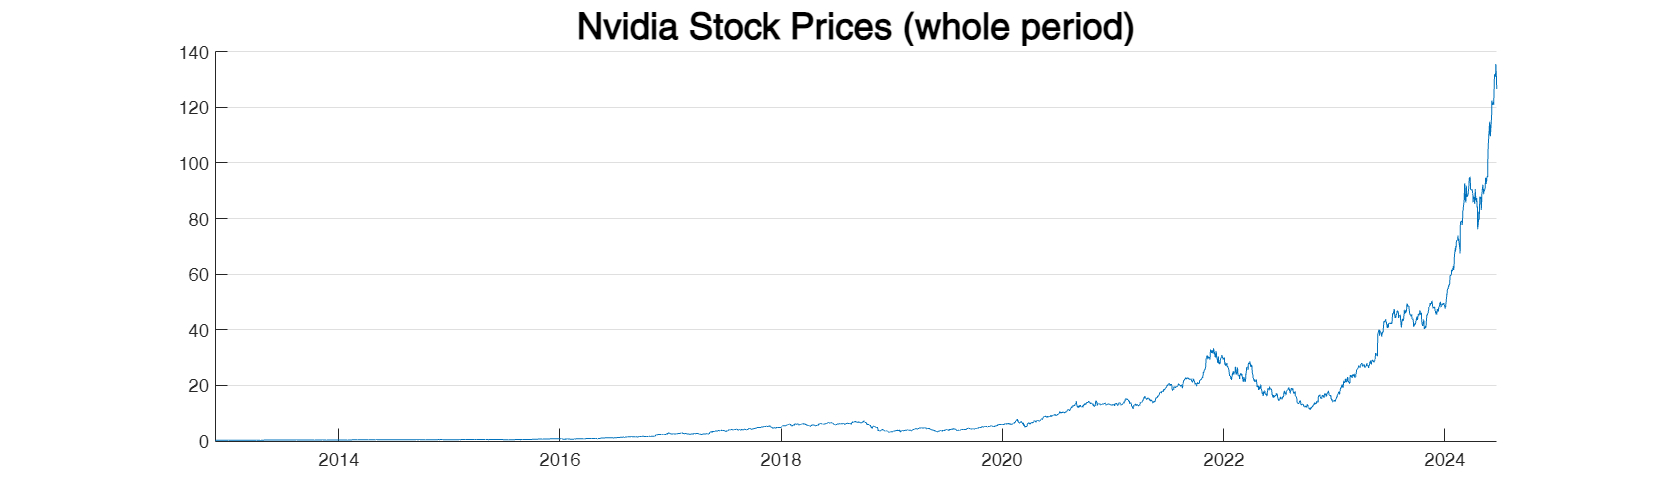

figure();
plot(dates, prices);
title("Nvidia Stock Prices (whole period)", "FontSize",20);
set(gca, "XGrid", "off", "YGrid", "on");
set(gcf, 'position', [10, 10, 2000, 600]);
box off

The time series is splitted in half and the visualization is performed on two different plots, in order to better understand the price levels before January 2016.

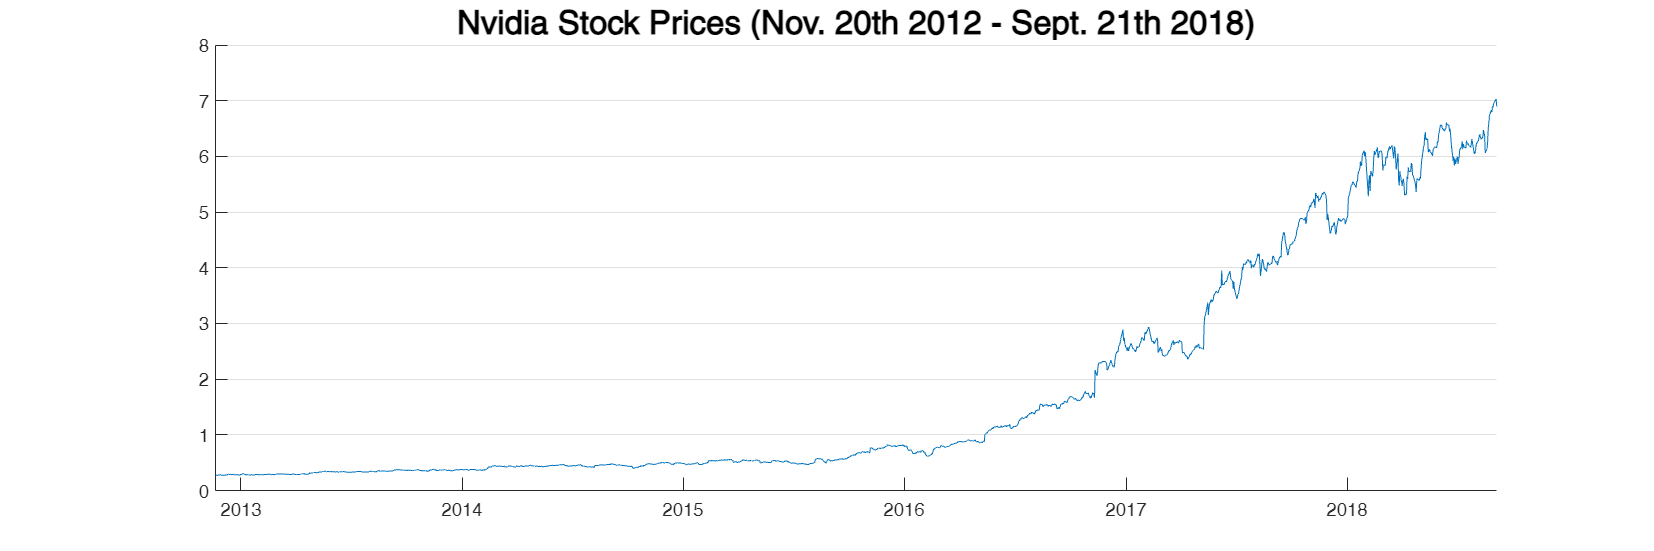

middleDay = round(length(prices)/2);
plot(dates(1:middleDay) , prices(1:middleDay));
title("Nvidia Stock Prices (Nov. 20th 2012 - Sept. 21th 2018)", "FontSize", 18);
set(gca, "XGrid", "off", "YGrid", "on");
set(gcf, 'position', [10, 10, 1800, 600]);
box off

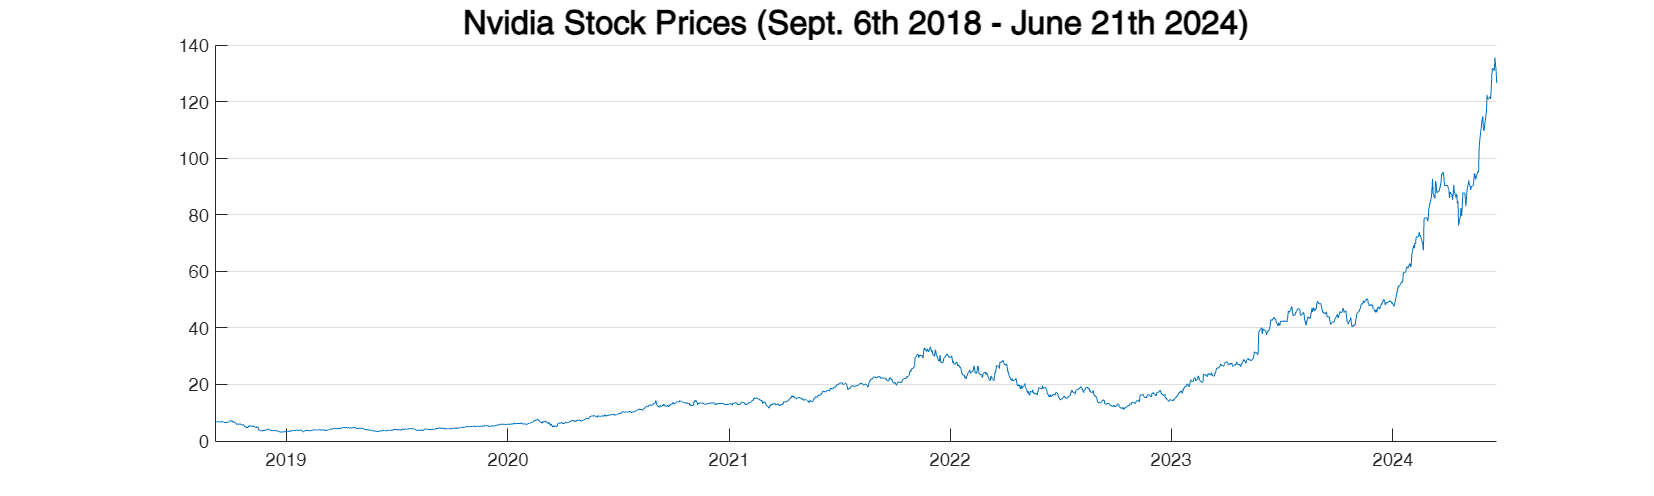

middleDayNext = round(length(prices)/2) + 1;

plot(dates(middleDayNext:end) , prices(middleDayNext:end));
title("Nvidia Stock Prices (Sept. 6th 2018 - June 21th 2024)", "FontSize", 18);
set(gca, "XGrid", "off", "YGrid", "on");
set(gcf, 'position', [10, 10, 2000, 600]);
box off

Given the quasi-exponential nature of the time series (especially in the second half), the series can be plotted in a logarithmic scale.

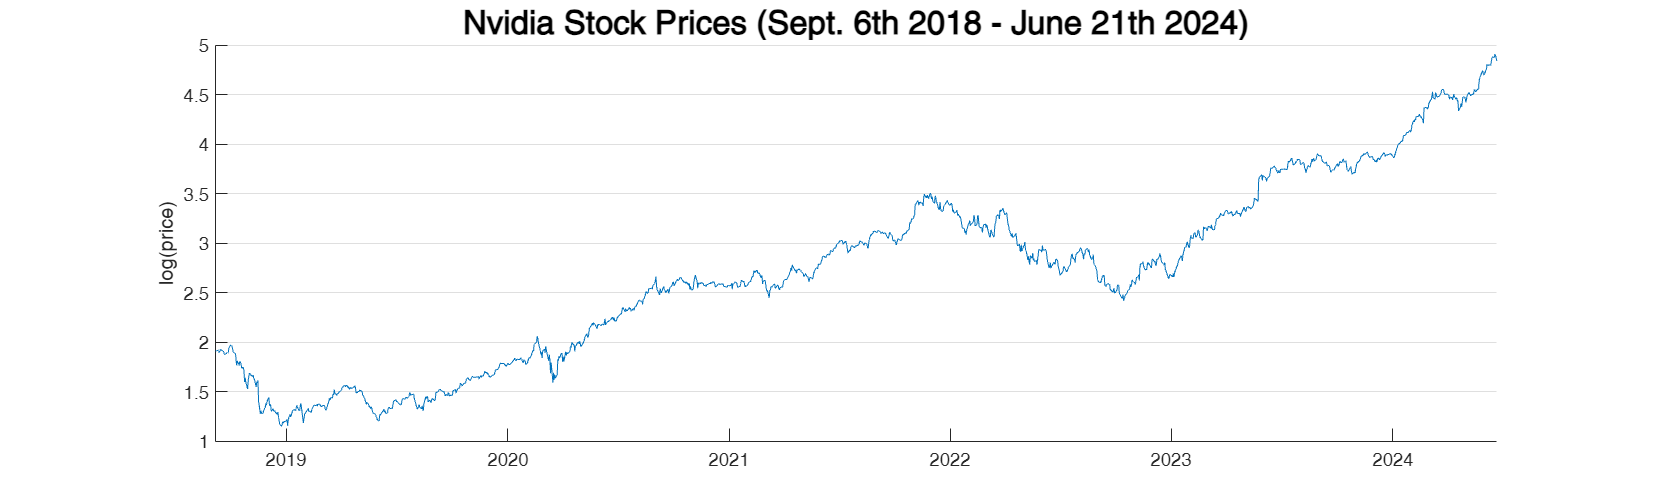

plot(dates(middleDayNext:end) , log(prices(middleDayNext:end)));
title("Nvidia Stock Prices (Sept. 6th 2018 - June 21th 2024)", "FontSize", 18);
set(gca, "XGrid", "off", "YGrid", "on");
ylabel("log(price)");
set(gcf, 'position', [10, 10, 2000, 600]);
box off

What interests the most to analysts and investors are not prices per se, but the stock **returns **(daily, monthly, yearly, ...).

Campbell, Lo and MacKinlay (1997) give two main reasons for using returns:

- for average investors, return of an asset is a complete and scale-free summary of the investment opportunity; 

- return series are easier to handle than price series because the former have more attractive statistical properties.

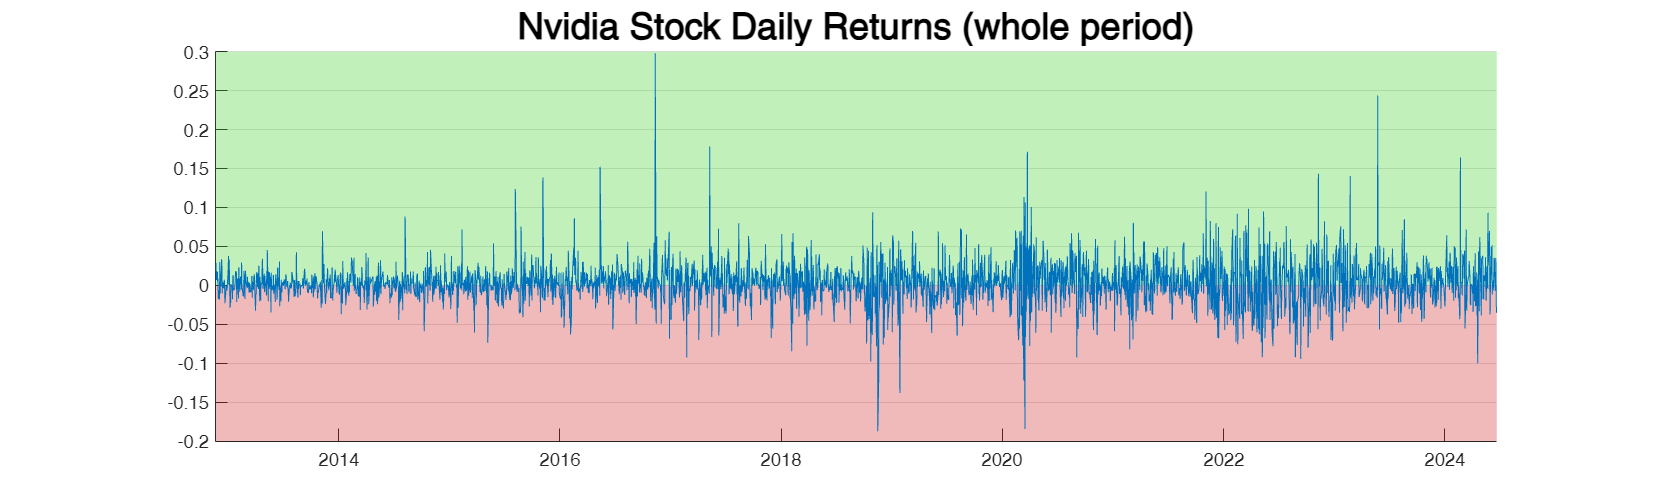

returns = tick2ret(prices); % function that converts price levels to return. Differencing causes the first observation to be lost.
figure();
hold on;
patch([dates(1), dates(end), dates(end), dates(1)], [0.3, 0.3, 0, 0], [0.2, 0.8, 0.1], "FaceAlpha", 0.3, "EdgeColor", "none")
patch([dates(1), dates(end), dates(end), dates(1)], [0, 0, -0.2, -0.2], [0.8, 0.1, 0.1], "FaceAlpha", 0.3, "EdgeColor", "none")
plot(dates(2:end), returns)
title("Nvidia Stock Daily Returns (whole period)", "FontSize",20);
set(gca, "XGrid", "off", "YGrid", "on");
set(gcf, 'position', [10, 10, 2000, 600]);
hold off;

This is the main time series of interest and inquiry. From here we can understand an essential phenomenon of financial markets, **volatility**, a process concerned with the evolution of conditional variance of the return over time. Interesting periods of volatility may be highlighted to analyze the phenomenon with proper models (GARCH and its broad range of extensions, Implied Volatility Estimation and so forth). More of that later in the Volatility Analysis section.

### Before going further: *gross *or *log-returns?*

The first important analyst decision (*forking path*) when it comes to analyzing financial data is to choose between *gross *or *log returns*.

Gross returns are [complete].

Log returns, instead, have more tractable statistical and mathematical properties. These are preferred for financial time series analysis, especially because the sample may more probably resemble a normal distribution (absolute higher values tend to be shrunk the most, less *fat-tailedness*) with a stable variance.

The logarithmic function is a monotonic transformation, hence only values magnitude change a bit, as shown below:

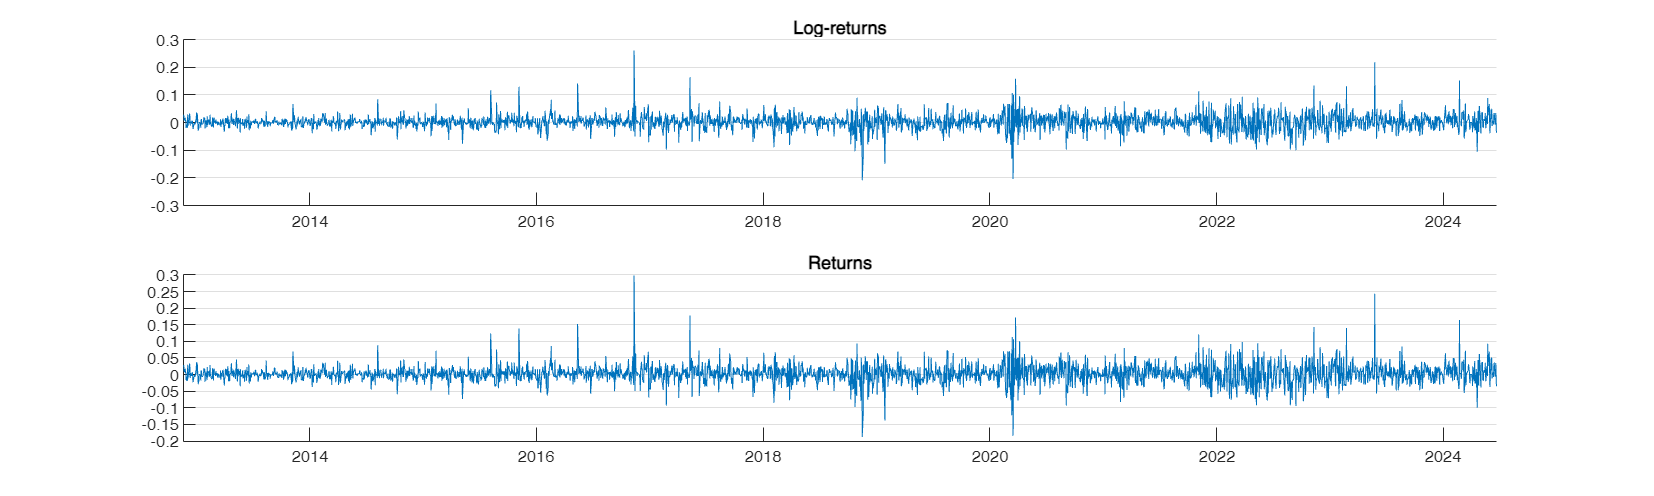

logreturns = log(1 + returns);
tiledlayout(2,1);

% Tile 1
nexttile
plot(dates(2:end), logreturns);
set(gca, "XGrid", "off", "YGrid", "on");
title("Log-returns");
box off;

%tile 2
nexttile
plot(dates(2:end), returns);
set(gca, "XGrid", "off", "YGrid", "on");
title("Returns");
box off;

For a better tractation on log transformations in economic and financial time series, read [*The Role of the Log Transformation in Forecasting Economic Variables*](https://papers.ssrn.com/sol3/papers.cfm?abstract_id=1368131) by *Helmut Lütkepohl* and *Fang Xu.*

*TL:DR: "For a range of economic variables substantial forecasting improvements from taking logs are found if the log transformation actually stabilizes the variance of the underlying series. Using logs can be*

*damaging for the forecast precision if a stable variance is not achieved."*

The analysis will be made both with simple and log-returns, in order to better understand the distributional differences, statistical properties and results.

### Descriptive Plots and Moments estimation

A common feature of most asset daily returns distributions is their ***fat-tailedness. ***This *fat-tailedness, *quantified by (excess) **kurtosis **(the 4th distribution moment), means that there is a higher probability of extreme events (returns much higher or lower than the average value) that fall outside 2-3 standard deviations (2-3σ) from the mean with respect to the normal distribution. This is one of the reason why assuming the normal distribution for either log-returns and simple returns is limited. Another reason is due to the **skewness **(3rd moment), where the distribution is not symmetrical around the mean.

Given a sufficient number of observations, it is possible to build the empirical distribution curve with both **Kernel Density Smoothing **and **histograms**. Both the KDE (continuous) and histogram (discrete) are *non-parametric *estimations of the theoretical PDF.

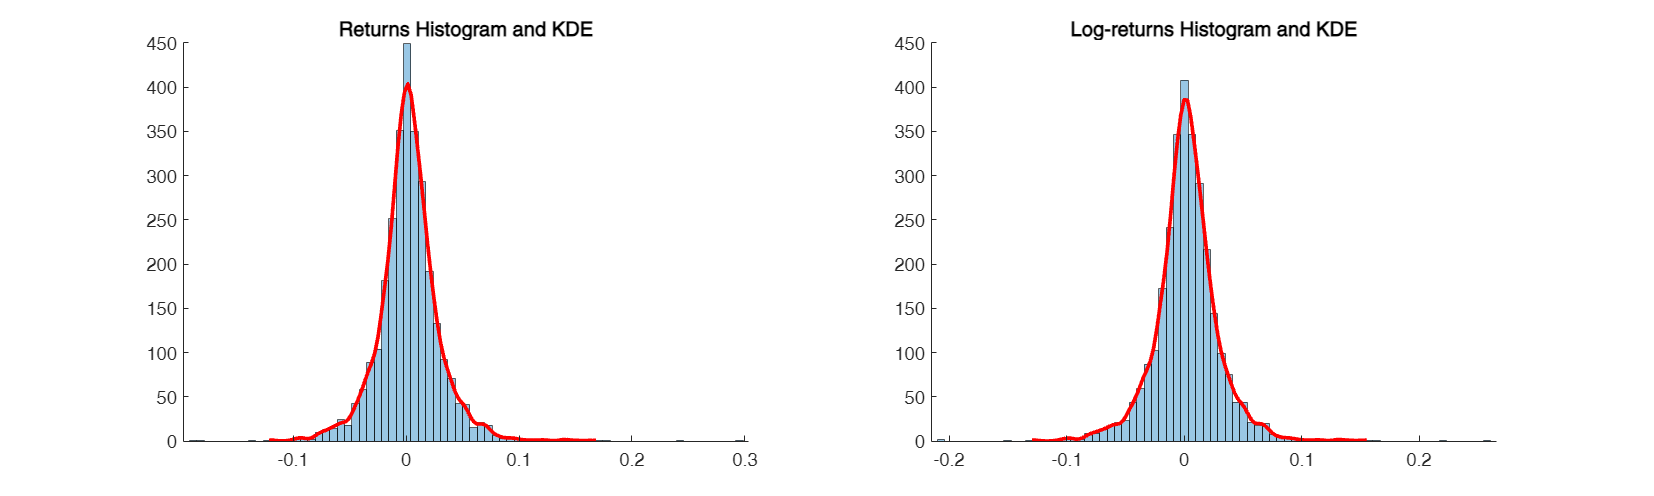

tiledlayout(1,2);

% Tile 1
ah1 = nexttile;
h1 = histfit(returns, 75, "kernel");
%% The "histfit" function belongs to the Statistics and Machine Learning Toolbox. It permits to simultaneously create a histogram and fit a kde, if specified. 
%% Distributions may be fitted (parametric).

%% histfit outputs a composite object, made of the kde curve and the histogram. These are called handles.
h1(1).FaceAlpha = 0.4; h1(1).EdgeAlpha = 0.6; %% Handle for histogram
h1(2).Color = "Red"; %% Handle for KDE curve
box off
title(ah1, "Returns Histogram and KDE")


% Tile 2
temp1 = nexttile;
h2 = histfit(logreturns, 75, "kernel");
%% The "histfit" function belongs to the Statistics and Machine Learning Toolbox. It permits to simultaneously create a histogram and fit a kde, if specified. 
%% Distributions may be fitted (parametric).

%% histfit outputs a composite object, made of the kde curve and the histogram. These are called handles.
h2(1).FaceAlpha = 0.4; h2(1).EdgeAlpha = 0.6; %% Handle for histogram
h2(2).Color = "Red"; %% Handle for KDE curve
title(temp1, "Log-returns Histogram and KDE")
box off

At first glance, the KDE curves recall a *leptokurtic normal distribution.*

Another common graphical method is the **Q-Q plot**, as it compares the sample quantiles to a specific distribution quantiles. It can also be used to compare two samples, to see whether they come from the same distribution (same hypothesis of the *two-sample Kolmogorov-Smirnov, *even though this one is a formal statistical test with its specific test statistic).

For now let's use it to compare our sample with the normal distribution:

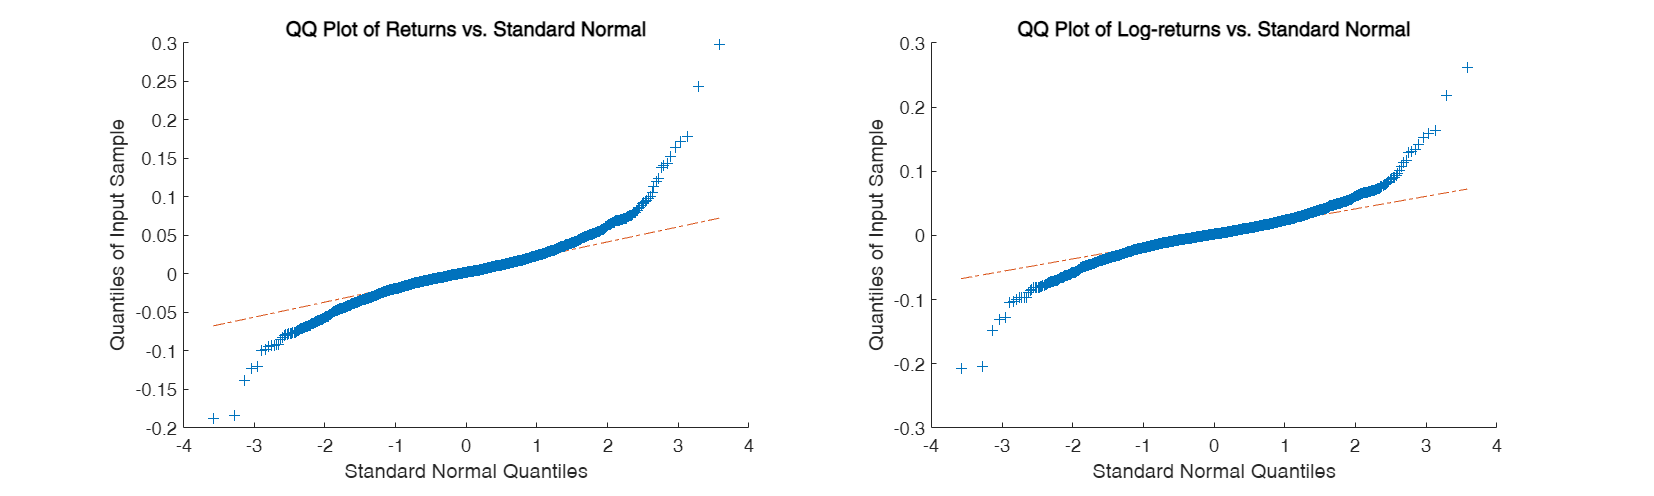

tiledlayout(1,2);

temp1 = nexttile;
qqplot(returns); %% the default hypothesized distribution is the normal one. Others can be considered.
title(temp1, "QQ Plot of Returns vs. Standard Normal")

temp2 = nexttile;
qqplot(logreturns);
title(temp2, "QQ Plot of Log-returns vs. Standard Normal")

The S-shaped data means the sample have "more extreme values" than the normal distribution. As expected, the log-returns sample tails are closer to the identity line, but not by much.

**Extreme Value Theory **is an important field of quantitative finance, especially for *risk management *(hedging strategies) and option pricing.

### Sample moments calculations

Function for estimating the first four moments (i.e., mean, variance, skewness, kurtosis) are coded:

1. Sample mean: $\hat{\mu} = \frac{1}{T}\sum^T_{t=1}x_t$

function myMean = calculateMean(sample)

The simple returns mean is: 0.00251


The log-returns mean is: 0.00212


  if ~isvector(sample) && ~ismatrix(sample) %& the ~ means "everything excluded"
    error('Input must be a vector or matrix of numbers.');
  end

  if ~isempty(sample)  % Avoid division by zero for empty arrays
    myMean = sum(sample) / length(sample);
  else
    myMean = NaN;  % Return NaN for empty arrays
  end
end

fprintf("The simple returns mean is: %.5f\n", calculateMean(returns));
fprintf("The log-returns mean is: %.5f\n", calculateMean(logreturns));

2. Sample variance:

function myVar = calculateVar(sample)

The simple returns variance is: 0.00080


The log-returns variance is: 0.00079


  biasCorr = 1/(length(sample) - 1);
  if ~isvector(sample) && ~ismatrix(sample) %& the ~ means "everything excluded"
    error('Input must be a vector or matrix of numbers.');
  end
  if ~isempty(sample)  % Avoid division by zero for empty arrays
    myVar = biasCorr * sum((sample - calculateMean(sample)).^2);
  else
    myVar = NaN;  % Return NaN for empty arrays
  end
end

fprintf("The simple returns variance is: %.5f\n", calculateVar(returns));
fprintf("The log-returns variance is: %.5f\n", calculateVar(logreturns));

3. Sample skewness:

function mySkew = calculateSkew(sample)

The simple returns skewness is: 0.71928


The log-returns skewness is: 0.26609


  biasCorr = 1/((length(sample) - 1) * sqrt(calculateVar(sample))^3); 
  if ~isvector(sample) && ~ismatrix(sample) % the '~' means "everything excluded"
    error('Input must be a vector or matrix of numbers.');
  end
  if ~isempty(sample)  % Avoid division by zero for empty arrays
    mySkew = biasCorr * sum((sample - calculateMean(sample)).^3);
  else
    mySkew = NaN;  % Return NaN for empty arrays
  end
end

fprintf("The simple returns skewness is: %.5f\n", calculateSkew(returns));
fprintf("The log-returns skewness is: %.5f\n", calculateSkew(logreturns));

4. Sample kurtosis:

function myKurt = calculateKurt(sample)

The returns kurtosis is: 13.17363


The log-returns kurtosis is: 11.40840


  biasCorr = 1/((length(sample) - 1) * calculateVar(sample)^2); 
  if ~isvector(sample) && ~ismatrix(sample) % the '~' means "everything excluded"
    error('Input must be a vector or matrix of numbers.');
  end
  if ~isempty(sample)  % Avoid division by zero for empty arrays
    myKurt = biasCorr * sum((sample - calculateMean(sample)).^4);

ans = 4×3 table
    Simple_Returns_Moment    Calculated    MATLAB_Func
    _____________________    __________    ___________

    "Mean"                   0.0025136      0.0025136 
    "Standard Deviation"      0.028259       0.028259 
    "Skewness"                 0.71928         0.7194 
    "Kurtosis"                  13.174         13.178 


  else
    myKurt = NaN;  % Return NaN for empty arrays
  end
end

fprintf("The returns kurtosis is: %.5f\n", calculateKurt(returns));

ans = 4×3 table
     Log_Returns_Moment     Calculated    MATLAB_Func
    ____________________    __________    ___________

    "Mean"                  0.0021167      0.0021167 
    "Standard Deviation"     0.028023       0.028023 
    "Skewness"                0.26609        0.26614 
    "Kurtosis"                 11.408         11.412 


fprintf("The log-returns kurtosis is: %.5f\n", calculateKurt(logreturns));

All calculated sample moments and MATLAB functions are tabulated to check if they coincide.

Simple_Returns_Moment = ["Mean"; "Standard Deviation"; "Skewness"; "Kurtosis"];

h0 = logical
   1


p_value = 8.2021e-16

d = 0.0778

Calculated = [calculateMean(returns); sqrt(calculateVar(returns)); calculateSkew(returns); calculateKurt(returns)];

h0 = logical
   1


p_value = 5.6998e-15

d = 0.0757

MATLAB_Func = [mean(returns); sqrt(var(returns)); skewness(returns); kurtosis(returns)];

table(Simple_Returns_Moment, Calculated, MATLAB_Func)

Log_Returns_Moment = ["Mean"; "Standard Deviation"; "Skewness"; "Kurtosis"];
Calculated = [calculateMean(logreturns); sqrt(calculateVar(logreturns)); calculateSkew(logreturns); calculateKurt(logreturns)];
MATLAB_Func = [mean(logreturns); sqrt(var(logreturns)); skewness(logreturns); kurtosis(logreturns)];

table(Log_Returns_Moment, Calculated, MATLAB_Func)

It is important to know that the *excess kurtosis* is the value of the calculated kurtosis minus 3. So there could be *mesokurtic, leptokurtic *and *platykurtic *sample distributions if this value is equal, higher or less than 0 (respectively).

### Formal Descriptive Tests

One of the most common type of statistical tests is the **test for normality **of a population, based on sample data. Many tests have been proposed throughout time with different testing strategies.

The performed tests (on both returns and log-returns) will be:

- Kolmogorov-Smirnov (1936);

- Anderson-Darling (1952);

- Shapiro-Wilk (1965);

- Lilliefors (1967);

- Jarque-Bera (1981).

#### Kolmogorov-Smirnov Test

The KS Test is a nonparametric test that compares the empirical cumulative distribution funtion with a hypothesized theoretical distribution. It can be used either to check whether a sample is a realization of a reference probability distribution (*one-sample KS test) *or whether two samples are the realizations of the same undefined probability distribution (*two-sample KS test*).

The **test statistic** is the supremum of the set of distances between the two cumulative distribution functions (empirical-theoretical or empirical-empirical). A discrete example of the KS-test below:


$$D_n = sup_x |F_n(x)-F(x)|$$


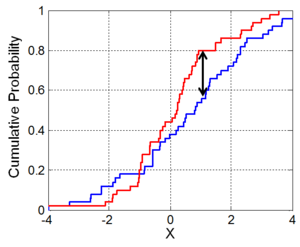

The first test will be the one-sample case. We will test whether our sample comes from a normal distribution or not:

[h0, p_value, d] = kstest(normalize(returns), "Alpha", 0.00001) %#ok<*ASGLU> % α significance level set to 0.00001 (the probability of committing a type I error)
[h0,p_value, d] = kstest(normalize(logreturns), "Alpha", 0.00001)

As expected, the null hypothesis for both the returns and log-returns being a realization of the normal distribution is rejected with a p-value virtually equal to 0 (i.e., *the probability of obtaining the test results at least as extreme as the result actually observed, ****under the assumption that the null hypothesis is correct****).*

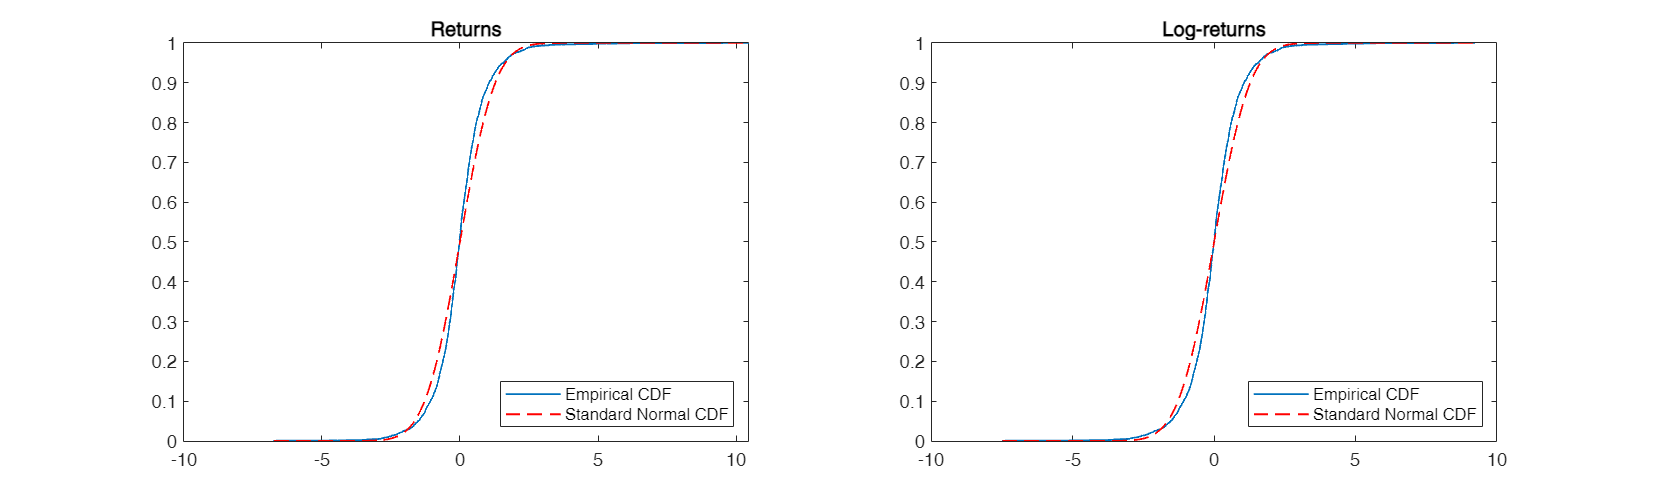

tiledlayout(1,2);

nexttile;

[f,x_values] = ecdf(normalize(returns));
J = plot(x_values,f);
hold on;
K = plot(x_values,normcdf(x_values),'r--');
set(J,'LineWidth', 1);
set(K,'LineWidth', 1);
legend([J K],'Empirical CDF','Standard Normal CDF','Location','SE');
title("Returns")

nexttile;


[f,x_values] = ecdf(normalize(logreturns));

h = logical
   0


d = 1.0000

p = 0.0062

J = plot(x_values,f);
hold on;
K = plot(x_values, normcdf(x_values),'r--');
set(J,'LineWidth', 1);
set(K,'LineWidth', 1);

h = logical
   1


p_value = 5.0000e-04

adstat = Inf

cv = 0.7517

legend([J K],'Empirical CDF','Standard Normal CDF','Location','SE');
title("Log-returns")

In the second test, the two-sample case, we will test the H0 that the log-returns and the simple returns are realizations of the same theoretical distribution:

[h, d, p] = kstest2(returns, logreturns, "Alpha" , 0.0001)

h = 1

p_value = 1.0000e-03

lstat = 0.0778

#### Anderson-Darling

One practical downside of the Kolmogorov-Smirnov test is its sensitivity to outliers, due to the test statistics itself (greatest distance of the differences), even though it has a strong mathematical-statistical underlying concept (the [Glivenko-Cantelli Theorem](https://en.wikipedia.org/wiki/Glivenko%E2%80%93Cantelli_theorem)). The Anderson-Darling test has the a similar underlying logic (it has a EDF statistic) and is a specific case of the *Cramer-von Mises Test.*


$$A^2 = n\int_{-\infty}^{\infty} [F_n(x)-F(x)]^2w(x)dF(x) \\ w(x) = [F(x)(1-F(x))]^{-1}$$


Thanks to the specific weight w(x), $A^2$ places more weights on tails' observations. The 

[h, p_value, adstat, cv] = adtest(returns)

Not enough input arguments.

Error in jbtest (line 73)
if ~isvector(x) || ~isreal(x)

#### Shapiro-Wilk


$$W = \frac{\bigg(\sum_{i=1}^na_ix_{(i)}\bigg)^2 }{\sum_{i=1}^n(x_i - \bar{x})^2}$$


%% This test is not avaiable in the Statistics and Machine Learning Toolbox.

#### Lilliefors

This test is essentially the same as the Kolmogorov-Smirnov test, with the same test statistics (greatest distance between the CDFs). While the KS-test is completely agnostic to the underlying distriburtion, the Lilliefors adds an assumption with the *estimates of *the mean and variance of the sample. This is why it is also called "Lilliefors c*orrected KS test*". It is more powerful than the KS version (*i.e.*, correctly reject the H0 of normal distribution).

[h, p_value, lstat] = lillietest(returns)

#### Jarque-Bera

This last test is different than the other ones. This test compares the sample skewness and kurtosis to the normal distribution. As we know, the normal distribution skewness and -excess- kurtosis are equal to zero. Technically, the H0 of the JB-test is a *joint *hypothesis of $S = 0 \cup K-3 = 0$.


$$JB = \frac{n}{6}\bigg(\hat{S}^2 + \frac{1}{4}(\hat{K} - 3)^2\bigg) \\
\hat{S} = \text{sample skewness}\\ \hat{K}\text{ = sample kurtosis}$$


jbtest()

In this large sample context, the empirical distributional convergence is . In these cases, more importance is given to the **effect size** than the actual test significance.

### Model Building Strategy

*Time Series Analysis; Forecasting and Control *by Box-Jenkins (1970) may be considered as The Bible of time series forecasting.

They proposed an *iterative three-stage modeling approach, *detailed below:

- **model identification and selection**;

- **parameter estimation **(model fitting);

- **statistical Model Checking **(diagnostics).

A powerful MATLAB tool for Time Series Analysis is the [**Econometric Modeller app**](https://it.mathworks.com/help/econ/econometric-modeler-overview.html). The app "*is well suited for visualizing and transforming data, performing statistical specification and model identification tests, fitting models to data, and iterating among these actions*".

The **autocorrelation function **is an essential descriptive tool for time series.

tiledlayout(2,1);

% Tile 1
nexttile
autocorr(returns)
title("ACF for Returns")

% Tile 1
nexttile
autocorr(logreturns)
title("ACF for Log-returns")

efheh

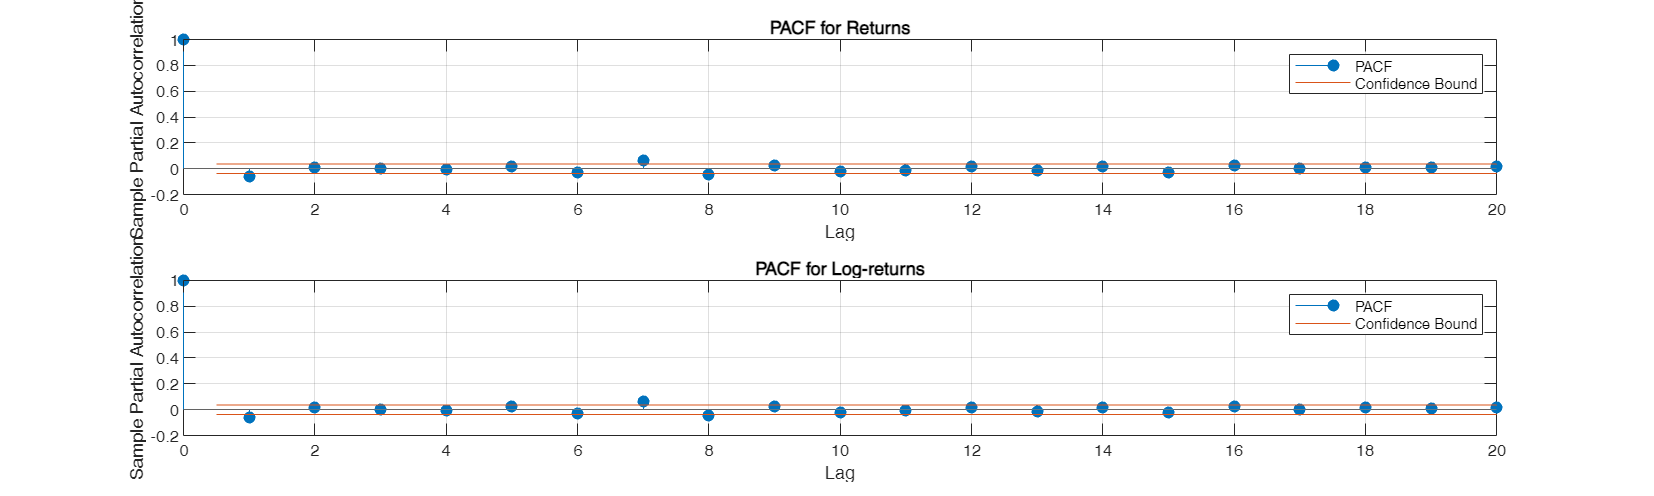

tiledlayout(2,1);

% Tile 1
nexttile
parcorr(returns)
title("PACF for Returns")

% Tile 1

nexttile
parcorr(logreturns)
title("PACF for Log-returns")

## Departures from Stationarity

### Trend

### Structural Breaks

*FindChangePoints*

Chow test

chowtest

## Analysis of Volatility / Heteroskedasticity